### 16-bit unsigned ADC Testing

N_ADC = 16;
Vref = 1;
LSB = Vref*2^(-N_ADC);

Vthres = LSB.*(1:2^(N_ADC)-1)

Vthres =     0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008


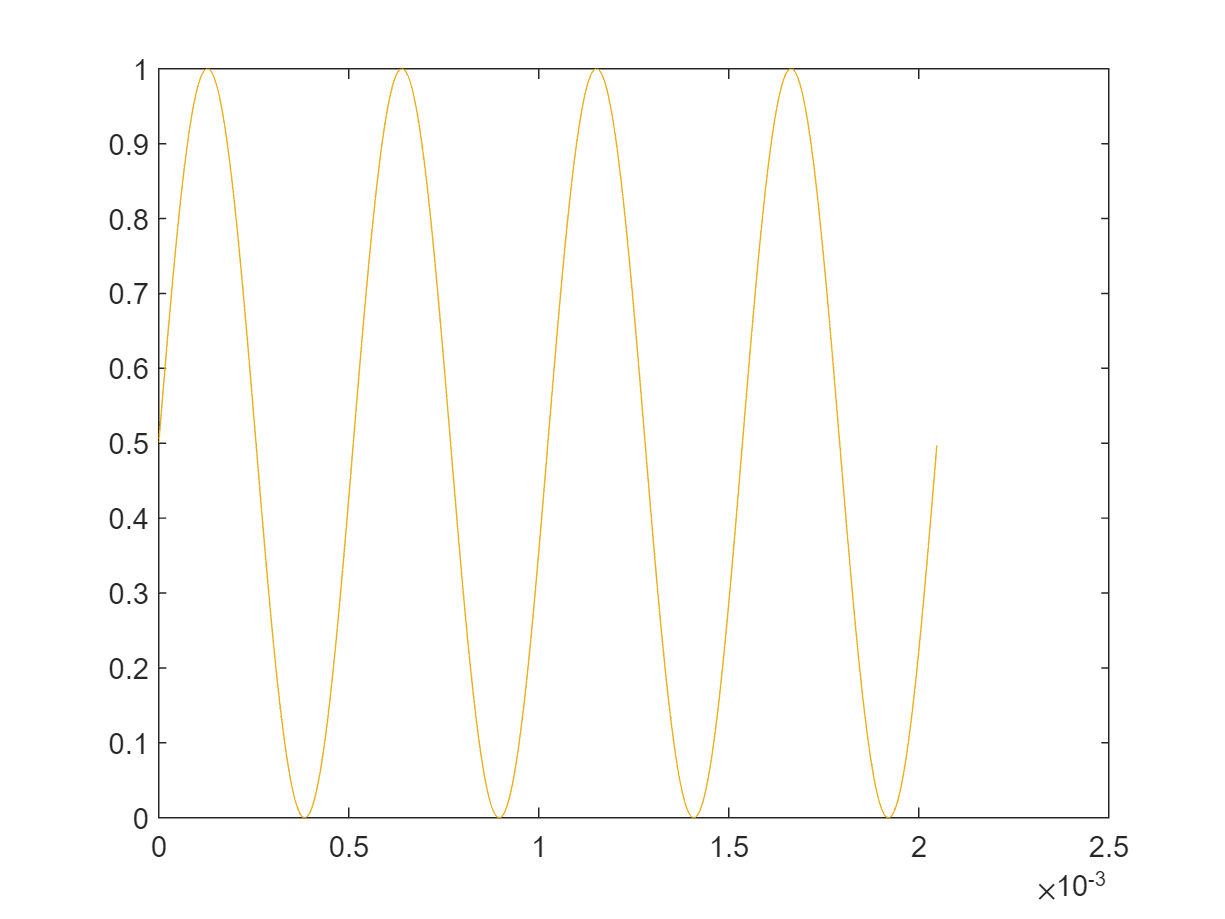

Fs = 2E6;
Fin = Fs * (1/1024);
t = (0:4095)/Fs;

Vsin = 0.5+0.5*sin(2*pi*Fin*t);
Vsin_quan = floor(Vsin/LSB).*LSB;
MAX_CODE = Vsin_quan >= Vref;
Vsin_quan = Vsin_quan - MAX_CODE*LSB;
Vsin_Dout = ADConversion_unsigned(Vsin, Vthres);
plot(t, [Vsin; Vsin_quan; Vsin_Dout.*LSB]);

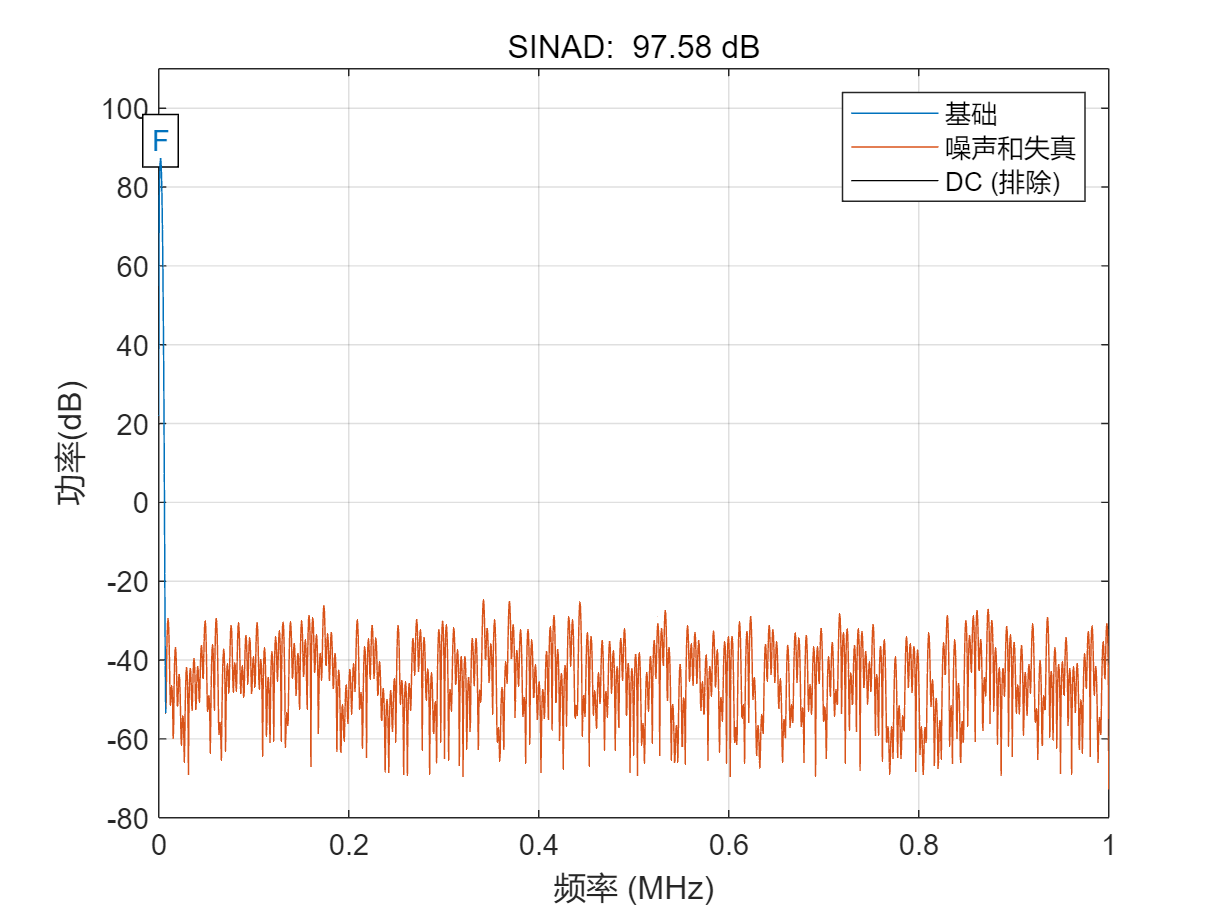

ans = 97.5806

sinad(Vsin_Dout, Fs)

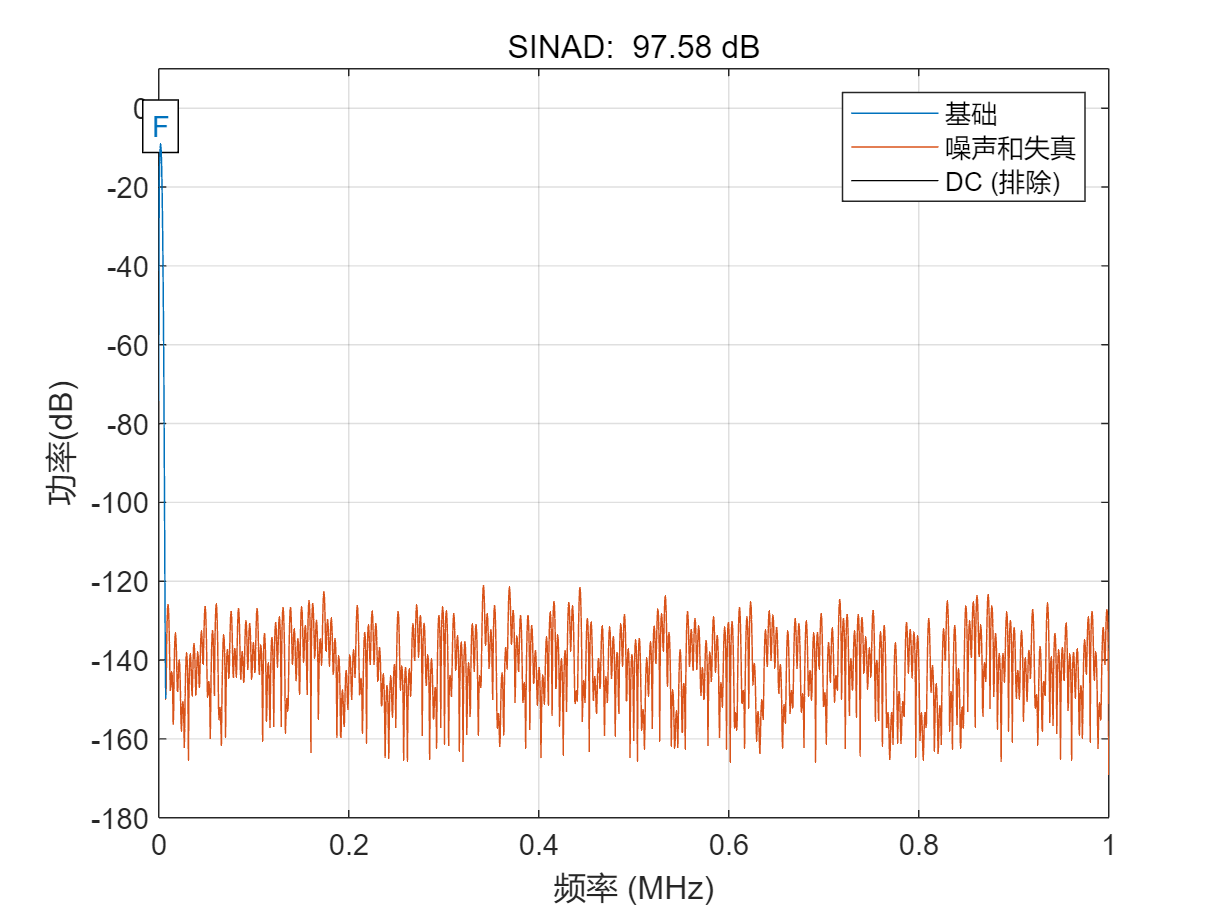

ans = 97.5806

sinad(Vsin_quan, Fs)

### 16-bit signed ADC Testing: 

N_code = 2^N_ADC;
Vref = 1;
LSB = Vref * 2^(-N_ADC+1);

Vthres = LSB.*(1:2^(N_ADC-1)-1);    % unsigned half
Vthres_full = LSB.* ((1:2^(N_ADC)-1)) - Vref;   % signed full

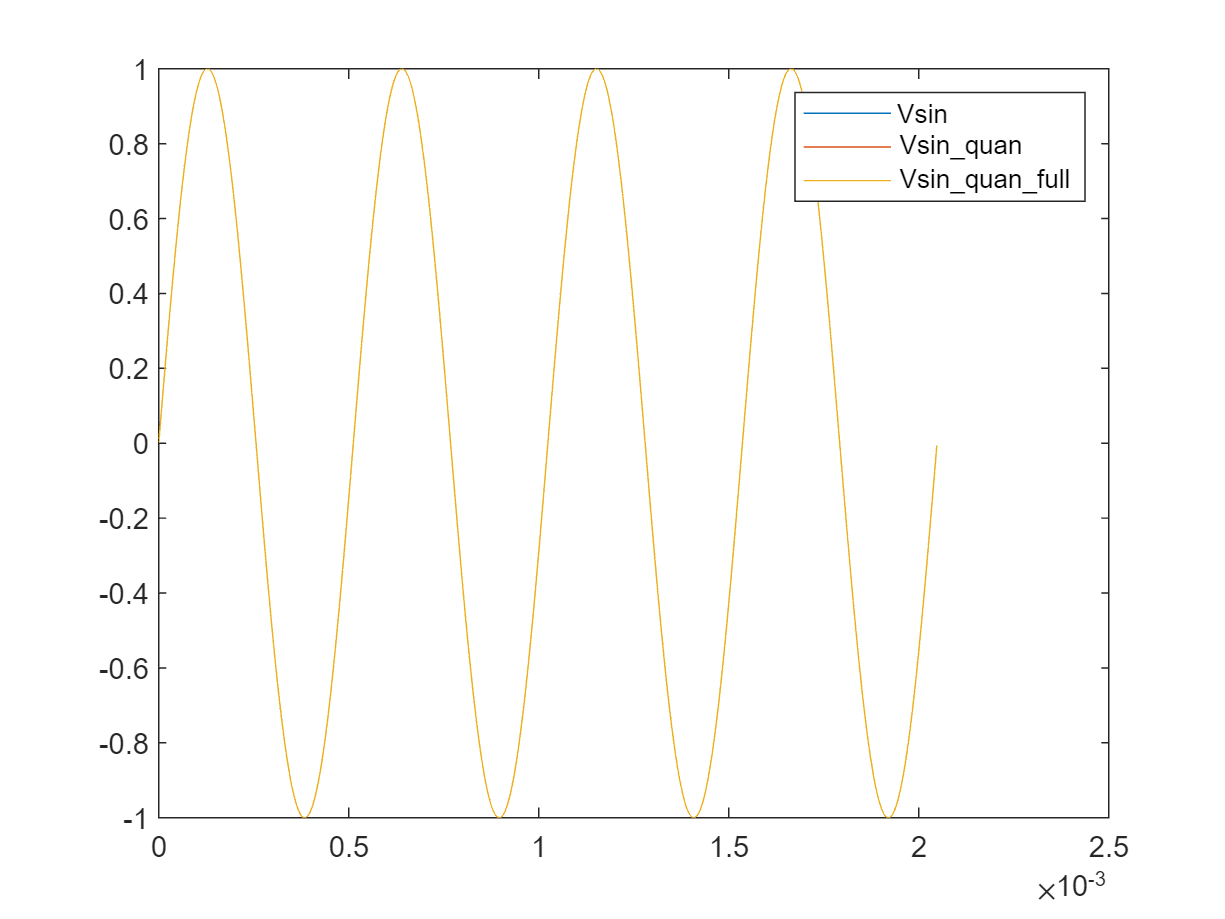

Fs = 2E6;
Fin = Fs * (1/1024);
t = (0:4095)/Fs;

Vsin = 1*sin(2*pi*Fin*t);
Vsin_quan = ADConversion_signed(Vsin, Vthres);
Vsin_quan_full = ADConversion_unsigned(Vsin, Vthres_full);
Vsin_quan_full = Vsin_quan_full.*LSB - Vref;

plot(t, [Vsin; Vsin_quan.*LSB; Vsin_quan_full]);
legend(["Vsin","Vsin\_quan","Vsin\_quan\_full"])

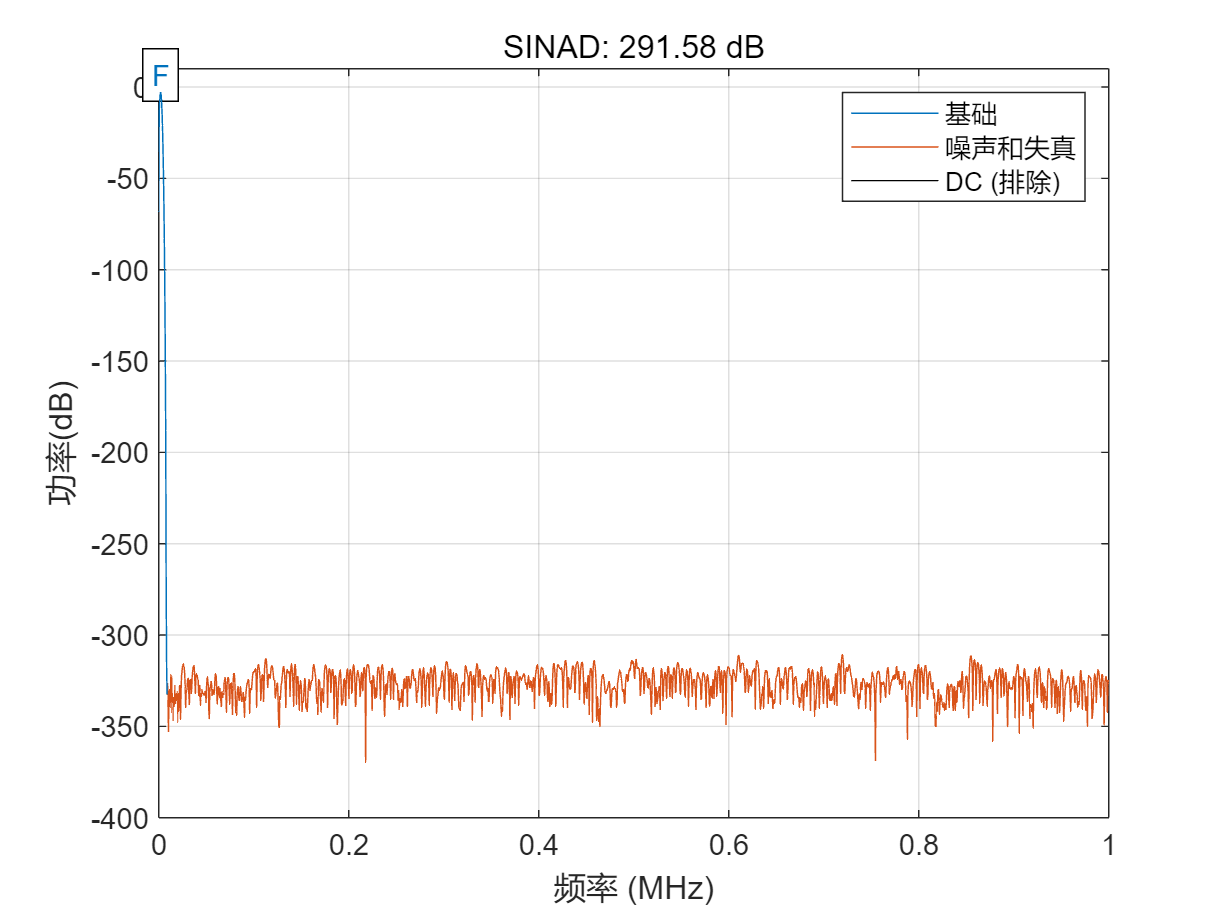

ans = 291.5762

sinad(Vsin, Fs)

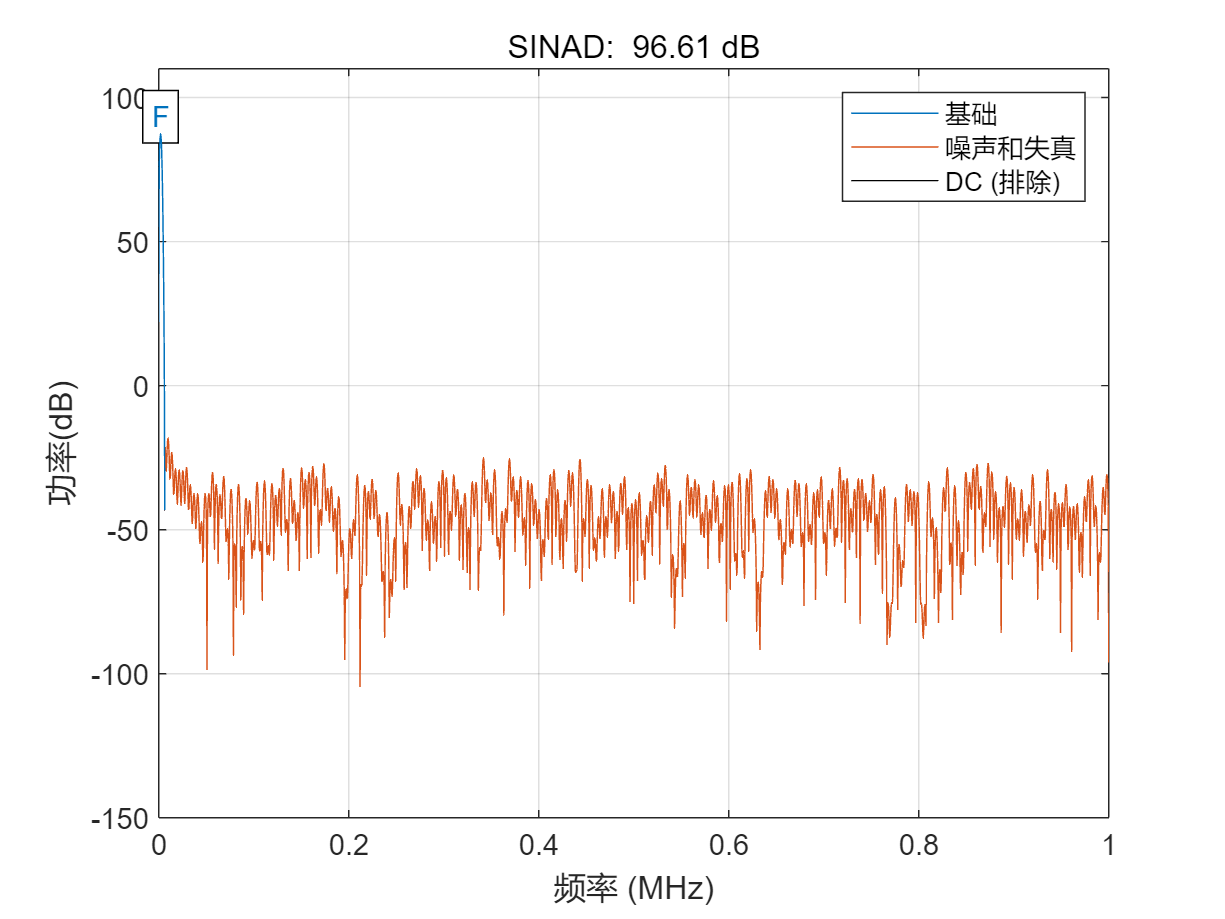

ans = 96.6089

sinad(Vsin_quan, Fs)    % 交越失真

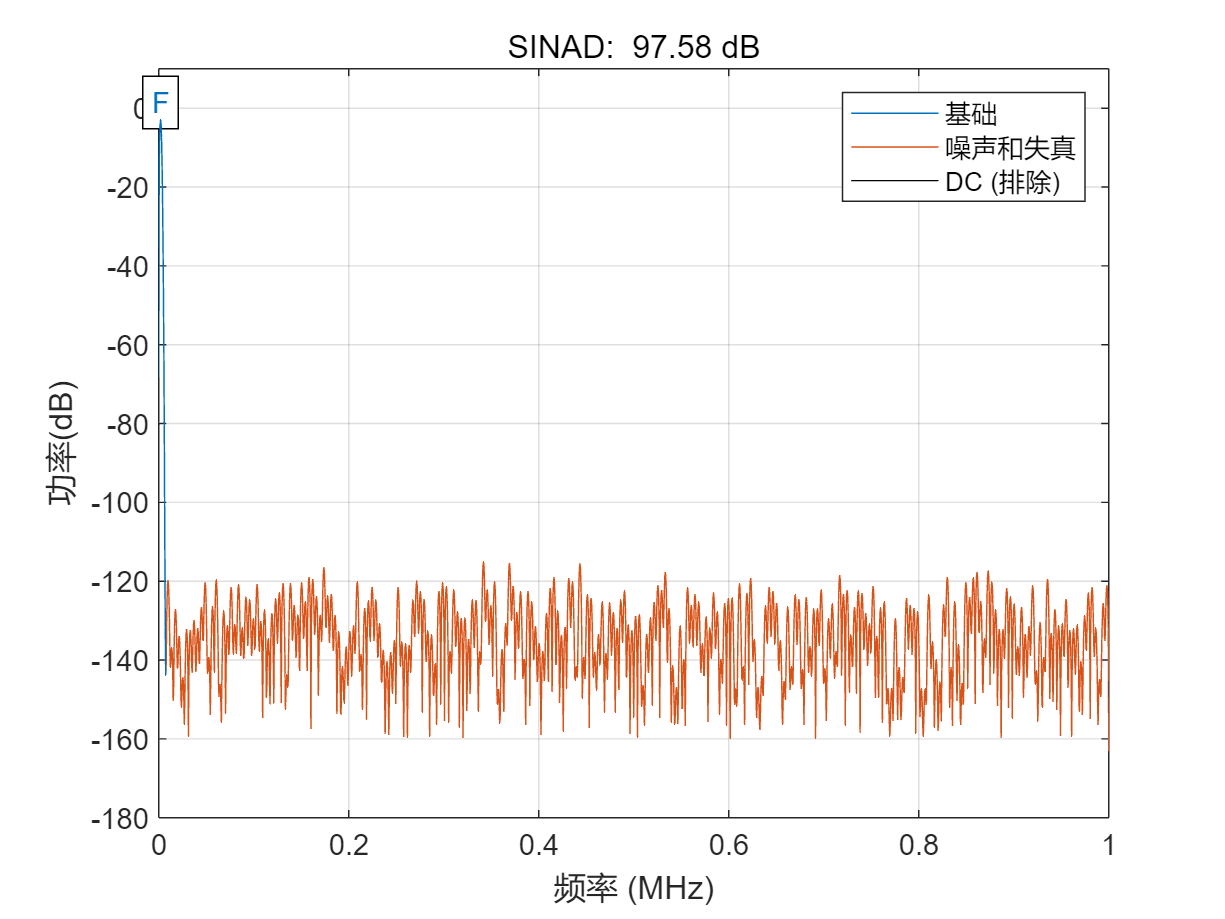

ans = 97.5806

sinad(Vsin_quan_full, Fs)

function Dout = ADConversion_unsigned(Vin, Vthres)
    Vin_len = length(Vin);
    Dout = zeros(1, Vin_len);
    for i = 1:Vin_len
        index_temp = Vin(i) > Vthres;
        Dout(i) = sum(index_temp);
    end
end

function Dout = ADConversion_signed(Vin, Vthres)
    Vin_len = length(Vin);
    Dout = zeros(1, Vin_len);
    Signed = Vin > 0;
    Signed = 2*Signed - 1;
    Vin_abs = abs(Vin);
    for i = 1:Vin_len
        index_temp = Vin_abs(i) > Vthres;
        Dout(i) = sum(index_temp);
    end
    Dout = Dout .* Signed;
end

function Dout = ADConversion_signed2(Vin, Vthres)
    Vin_len = length(Vin);
    Dout = zeros(1, Vin_len);
    for i = 1:Vin_len
        index_temp = Vin(i) > Vthres;
        Dout(i) = sum(index_temp);
    end
end